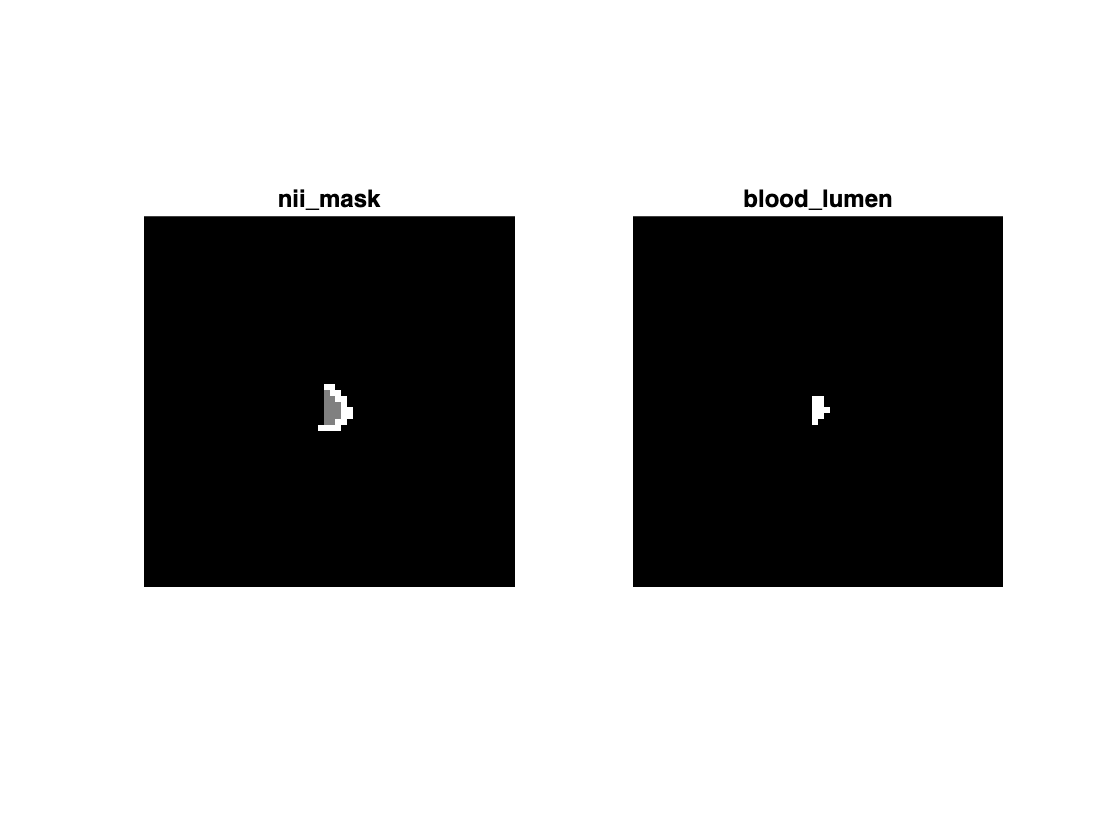

% Load data
nii_t1 = double(niftiread('data/T1_014_0000.nii.gz'));
nii_mask = niftiread('data/T1_014_label.nii.gz');

% Segment blood lumen
blood_threshold = 0.3 * max(nii_t1(nii_mask > 0));
blood_lumen = (nii_t1 < blood_threshold) & (nii_mask > 0);

% Visualize middle slice (adjust slice number if needed)
slice_idx = round(size(nii_mask, 3) / 2);

figure;
subplot(1,2,1);
imagesc(nii_mask(:,:,slice_idx));
axis image off;
title('nii\_mask');

subplot(1,2,2);
imagesc(blood_lumen(:,:,slice_idx));
axis image off;
title('blood\_lumen');
colormap gray;

% Calculate volumes
mask_volume = sum(nii_mask(:));
lumen_volume = sum(blood_lumen(:));
blood_fraction = lumen_volume / mask_volume;

fprintf('Mask volume = %d voxels\n', mask_volume);

Mask volume = 385 voxels


fprintf('Blood lumen volume = %d voxels\n', lumen_volume);

Blood lumen volume = 50 voxels


fprintf('Blood lumen fraction = %.2f%%\n', blood_fraction * 100);

Blood lumen fraction = 12.99%


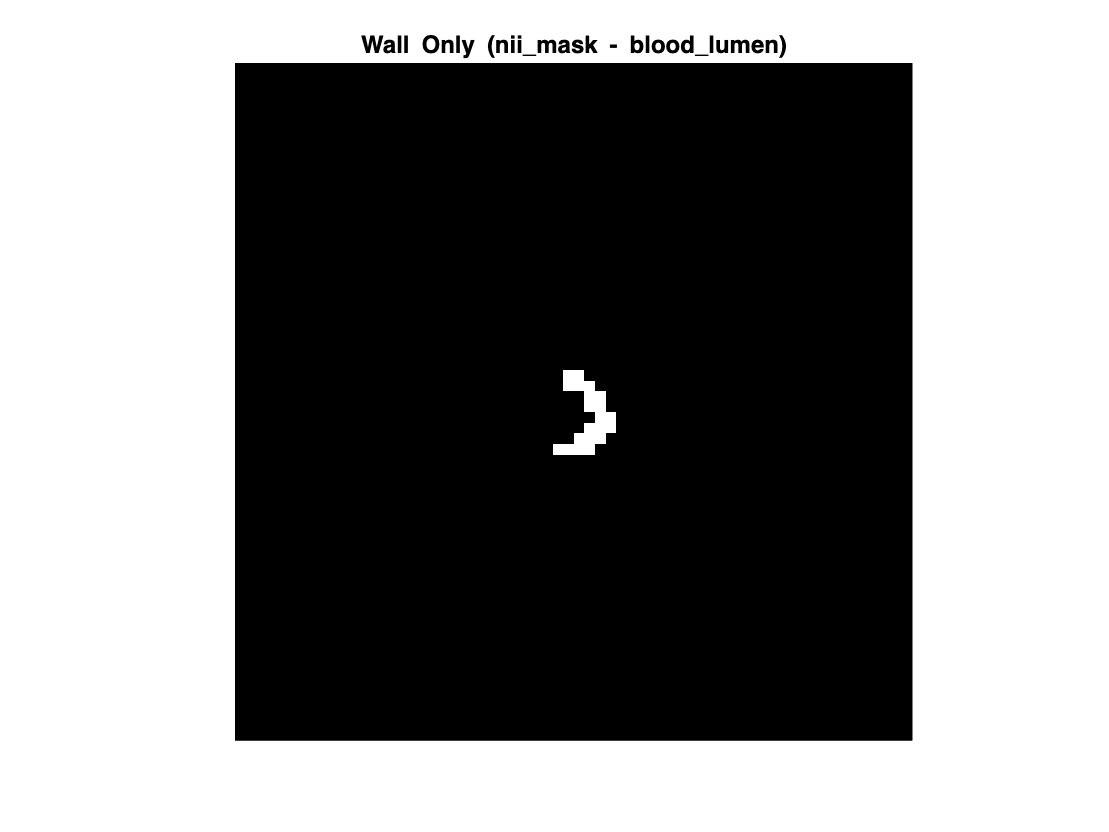

% Subtract blood lumen from mask
wall_only = nii_mask & (~blood_lumen);

% Visualize middle slice
slice_idx = round(size(wall_only, 3) / 2);

figure;
imagesc(wall_only(:,:,slice_idx));
axis image off;
title('Wall Only (nii\_mask - blood\_lumen)');
colormap gray;

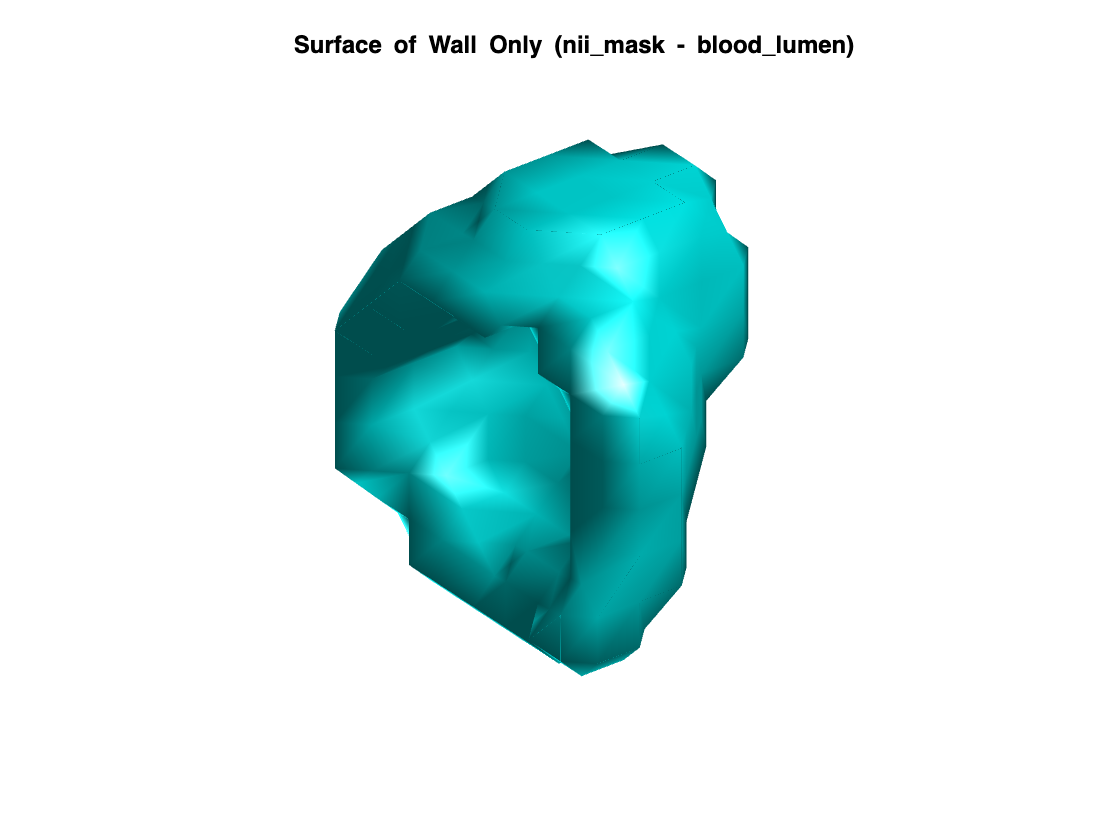

% Extract wall surface
fv_wall = isosurface(wall_only, 0.5);

% Visualize
figure;
trisurf(fv_wall.faces, fv_wall.vertices(:,1), fv_wall.vertices(:,2), fv_wall.vertices(:,3), ...
    'FaceColor', 'cyan', 'EdgeColor', 'none');
axis equal off;
view(3);
camlight;
lighting gouraud;
title('Surface of Wall Only (nii\_mask - blood\_lumen)');

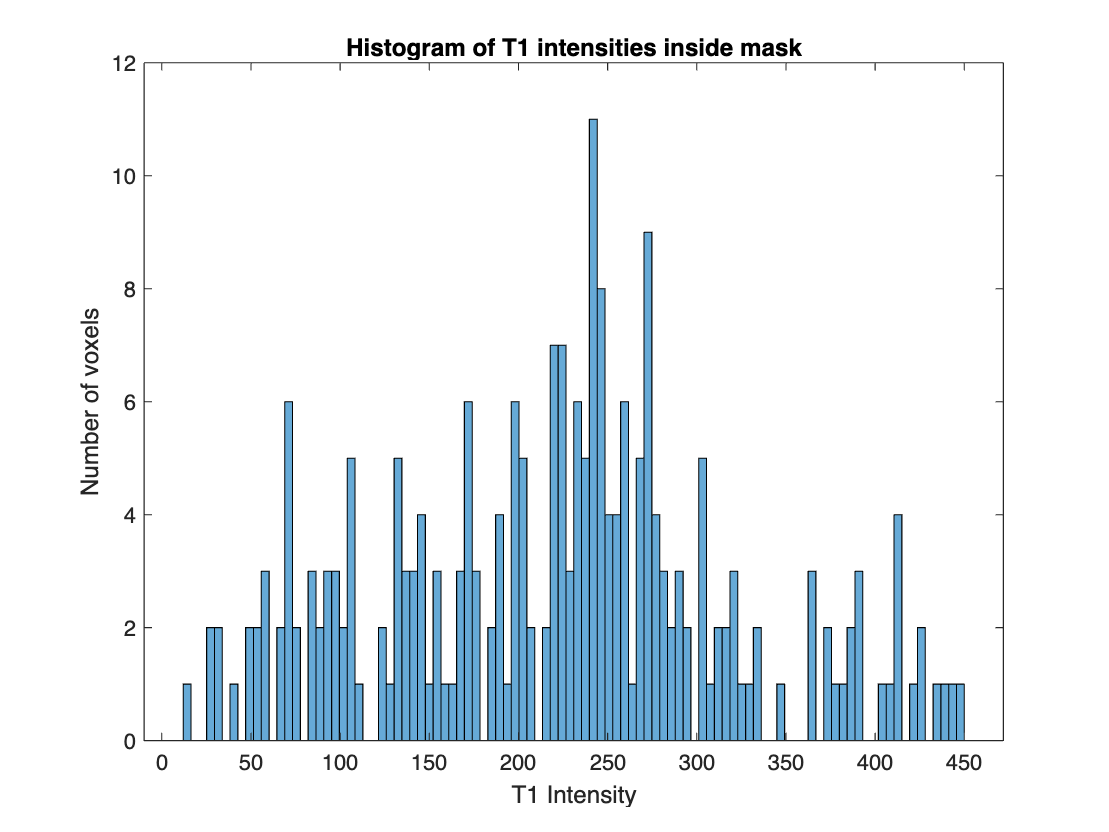

% Get T1 values inside mask
t1_inside_mask = nii_t1(nii_mask > 0);

% Plot histogram
figure;
histogram(t1_inside_mask, 100);
xlabel('T1 Intensity');
ylabel('Number of voxels');
title('Histogram of T1 intensities inside mask');